# Lidar 3-D Object Detection Using PointPillars Deep Learning

This example shows how to train a PointPillars network for object detection in point clouds.

Point cloud data is acquired by a variety of sensors, such as lidar sensors, radar sensors, and depth cameras. These sensors capture 3-D position information about objects in a scene, which is useful for many applications in autonomous driving and augmented reality. However, training robust detectors with point cloud data is challenging because of the sparsity of data per object, object occlusions, and sensor noise. Deep learning techniques have been shown to address many of these challenges by learning robust feature representations directly from point cloud data. One deep learning technique for 3-D object detection is PointPillars [1]. Using a similar architecture to PointNet, the PointPillars network extracts dense, robust features from sparse point clouds called pillars, then uses a 2-D deep learning network with a modified SSD object detection network to get joint bounding box and class predictions.

This example uses a data set of highway scenes collected using the Ouster OS1 lidar sensor. 

## Download Pretrained Network

Download the pretrained network from the given URL using the helper function `downloadPretrainedPointPillarsNet`, defined at the end of this example. The pretrained model allows you to run the entire example without having to wait for training to complete. If you want to train the network, set the `doTraining` variable to `true`.

% outputFolder = fullfile(tempdir,'WPI');
outputFolder = fullfile('/home/tianqiu/Downloads','trainedPointPillars');
pretrainedNetURL = 'https://ssd.mathworks.com/supportfiles/lidar/data/trainedPointPillars.zip';

doTraining = false;
if ~doTraining
    net = downloadPretrainedPointPillarsNet(outputFolder, pretrainedNetURL);
end

## Load Data

Download the highway scenes dataset from the given URL using the helper function `downloadWPIData`, defined at the end of this example. The data set contains 1617 full 360-degree view organized lidar point cloud scans of highway scenes and corresponding labels for car and truck objects.

lidarURL = 'https://www.mathworks.com/supportfiles/lidar/data/WPI_LidarData.tar.gz';
outputFolder = fullfile('/home/tianqiu/Downloads','WPI_LidarData');
lidarData = downloadWPIData(outputFolder, lidarURL);

Note: Depending on your Internet connection, the download process can take some time. The code suspends MATLAB® execution until the download process is complete. Alternatively, you can download the data set to your local disk using your web browser and extract the file. If you do so, change the `outputFolder` variable in the code to the location of the downloaded file. 

Load the 3-D bounding box labels.

load('WPI_LidarGroundTruth.mat','bboxGroundTruth');
Labels = timetable2table(bboxGroundTruth);
Labels = Labels(:,2:end);

Display the full-view point cloud.

figure
ax = pcshow(lidarData{1,1}.Location);

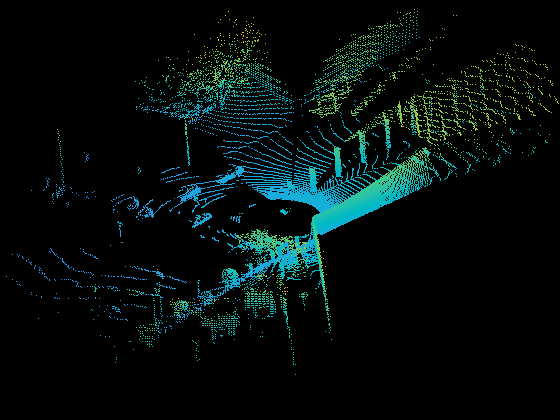

set(ax,'XLim',[-50 50],'YLim',[-40 40]);
zoom(ax,2.5);
axis off;

## Preprocess Data

This example crops full-view point clouds to front-view point clouds using the standard parameters [1]. These parameters help choose the size of the input passed to the network. Selecting a smaller range of point clouds along x, y, and z-axis helps detect objects that are closer to the origin and also decreases the overall training time of the network. 

xMin = 0.0;     % Minimum value along X-axis.
yMin = -39.68;  % Minimum value along Y-axis.
zMin = -5.0;    % Minimum value along Z-axis.
xMax = 69.12;   % Maximum value along X-axis.
yMax = 39.68;   % Maximum value along Y-axis.
zMax = 5.0;     % Maximum value along Z-axis.
xStep = 0.16;   % Resolution along X-axis.
yStep = 0.16;   % Resolution along Y-axis.
dsFactor = 2.0; % Downsampling factor.

% Calculate the dimensions for pseudo-image.
Xn = round(((xMax - xMin) / xStep));
Yn = round(((yMax - yMin) / yStep));

% Define pillar extraction parameters.
gridParams = {{xMin,yMin,zMin},{xMax,yMax,zMax},{xStep,yStep,dsFactor},{Xn,Yn}};

Crop the front view of the point clouds using the `createFrontViewFromLidarData` helper function, attached to this example as a supporting file, and lidar camera calibration values. Skip this step if your data set contains front view point clouds.

% Load the calibration parameters.
fview = load('calibrationValues.mat');
[inputPointCloud, boxLabels] = createFrontViewFromLidarData(lidarData, Labels, gridParams, fview); 

Processing data 100% complete

Display the cropped point cloud.

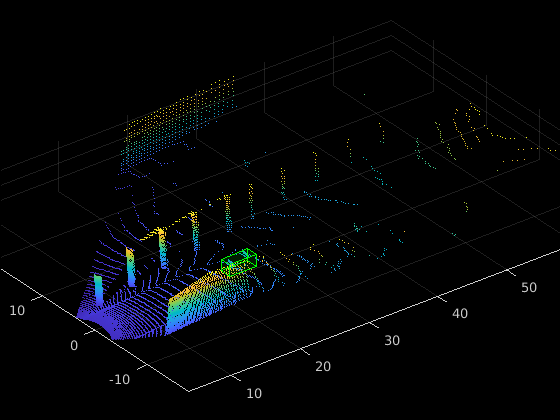

figure
ax1 = pcshow(inputPointCloud{1,1}.Location);
gtLabels = boxLabels.car(1,:);
showShape('cuboid', gtLabels{1,1}, 'Parent', ax1, 'Opacity', 0.1, 'Color', 'green','LineWidth',0.5);
zoom(ax1,2);

## Create FileDatastore and BoxLabelDatastore Objects for Training

Split the data set into a training set for training the network, and a test set for evaluating the network. Select 70% of the data for training. Use the rest for evaluation.

rng(1);
shuffledIndices = randperm(size(inputPointCloud,1));
idx = floor(0.7 * length(shuffledIndices));

trainData = inputPointCloud(shuffledIndices(1:idx),:);
testData = inputPointCloud(shuffledIndices(idx+1:end),:);

trainLabels = boxLabels(shuffledIndices(1:idx),:);
testLabels = boxLabels(shuffledIndices(idx+1:end),:);

For easy access with datastores, save the training data as PCD files. Skip this step if your point cloud data format is supported by [pcread](docid:vision_ref#buphpf3-1) function.

dataLocation = fullfile(outputFolder,'InputData');
saveptCldToPCD(trainData,dataLocation);

Processing data 100% complete

Create [FileDatastore](docid:matlab_ref#bvako8w) to load PCD files using the [pcread](docid:vision_ref#buphpf3-1) function.

lds = fileDatastore(dataLocation,'ReadFcn',@(x) pcread(x));

Create [BoxLabelDatastore](docid:vision_ref#mw_ea7fe152-be5c-4868-acb6-7c5d7fd40b93) for loading the 3-D bounding box labels.

bds = boxLabelDatastore(trainLabels);

Use the [combine](docid:matlab_ref#mw_b02645f0-b121-4bee-a5c0-1c669ce05793) function to combine the point clouds and 3-D bounding box labels into a single datastore for training.

cds = combine(lds,bds);

## Data Augmentation

This example uses ground truth data augmentation and several other global data augmentation techniques to add more variety to the training data and corresponding boxes.

Read and display a point cloud before augmentation.

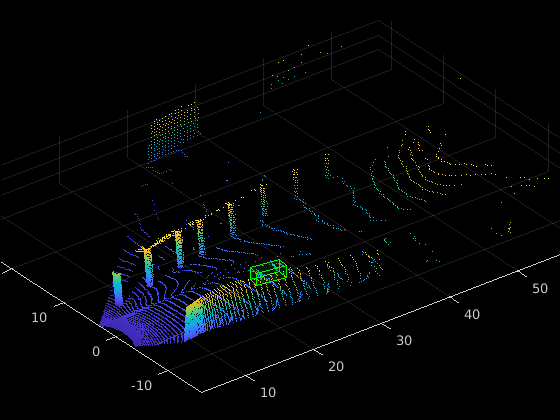

augData = read(cds);
augptCld = augData{1,1};
augLabels = augData{1,2};
figure;
ax2 = pcshow(augptCld.Location);
showShape('cuboid', augLabels, 'Parent', ax2, 'Opacity', 0.1, 'Color', 'green','LineWidth',0.5);
zoom(ax2,2);

reset(cds);

Use `generateGTDataForAugmentation` helper function, attached to this example as a supporting file, to extract all ground truth bounding boxes from training data.

gtData = generateGTDataForAugmentation(trainData,trainLabels);

Use the `groundTruthDataAugmentation` helper function, attached to this example as a supporting file, to randomly add a fixed number of car class objects to every point cloud.

Use the [transform](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function to apply ground truth and custom data augmentations to the training data.

cdsAugmented = transform(cds,@(x) groundTruthDataAugmenation(x,gtData));

 In addition, apply the following data augmentations to every point cloud.

-  Random flipping along the x-axis

-  Random scaling by 5 percent

-  Random rotation along z-axis from [-pi/4, pi/4]

-  Random translation by [0.2, 0.2, 0.1] meters along XYZ axis respectively

cdsAugmented = transform(cdsAugmented,@(x) augmentData(x));

Display an augmented point cloud along with ground truth augmented boxes.

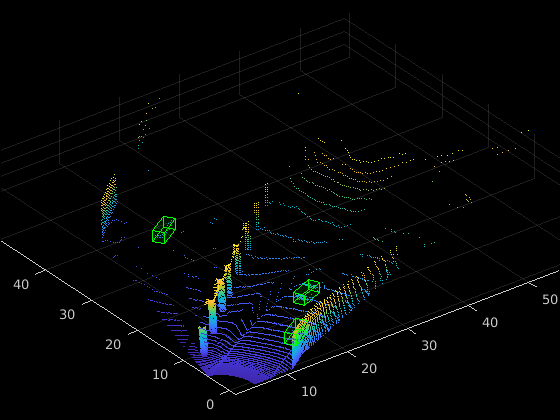

augData = read(cdsAugmented);
augptCld = augData{1,1};
augLabels = augData{1,2};
figure;
ax3 = pcshow(augptCld(:,1:3));
showShape('cuboid', augLabels, 'Parent', ax3, 'Opacity', 0.1, 'Color', 'green','LineWidth',0.5);
zoom(ax3,2);

reset(cdsAugmented);

## Extract Pillar Information from Point Clouds

Convert 3-D point cloud to 2-D representation, to apply 2-D convolution architecture to point clouds for faster processing. Use the [transform](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with `createPillars` helper function, attached to this example as a supporting file, to create pillar features and pillar indices from the point clouds. The helper function performs the following operations:

- Discretize 3-D point clouds into evenly spaced grids in the x-y plane to create a set vertical columns called pillars.

- Select prominent pillars (P) based on number of points per pillar (N).

- Compute distance to the arithmetic mean of all points in the pillar.

- Compute offset from the pillar center.

- Use x, y, z location, intensity, distance and offset values to create nine dimensional (9-D) vector for each point in the pillar.

% Define number of prominent pillars.
P = 12000; 

% Define number of points per pillar.
N = 100;   
cdsTransformed = transform(cdsAugmented,@(x) createPillars(x,gridParams,P,N));

## Define PointPillars Network

The PointPillars network uses a simplified version of PointNet network, that takes pillar features as input. For each pillar feature, a linear layer is applied followed by batch normalization and ReLU layers. Finally, max-pooling operation over the channels is applied to get high level encoded features. These encoded features are scattered back to the original pillar locations to create a pseudo-image using custom layer `helperscatterLayer`, attached to this example as a supporting file. The pseudo-image is then processed with a 2-D convolutional backbone followed by various SSD detection heads to predict the 3-D bounding boxes along with its classes.

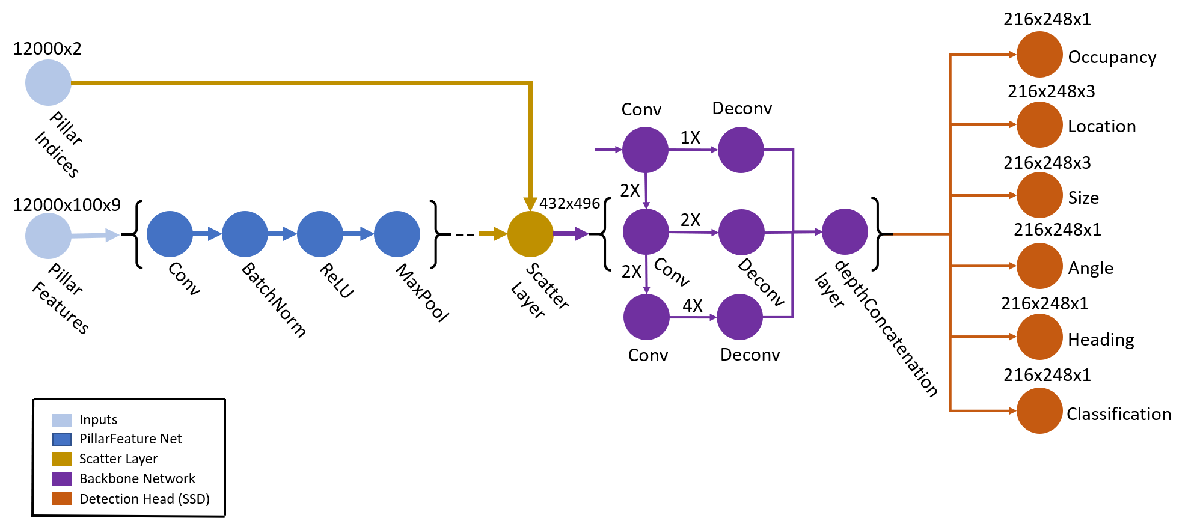

Define the anchor box dimensions based on the classes to detect. Typically, these dimensions are the means of all the bounding box values in the training set [1]. The anchor boxes are defined in the format *{length, width, height, z-centre, yaw angle}.*

anchorBoxes = {{3.9, 1.6, 1.56, -1.78, 0}, {3.9, 1.6, 1.56, -1.78, pi/2}};
numAnchors = size(anchorBoxes,2);
classNames = trainLabels.Properties.VariableNames;

Next create the PointPillars network using the helper function `pointpillarNetwork`, attached to this example as a supporting file.

lgraph = pointpillarNetwork(numAnchors,gridParams,P,N);

## Specify Training Options

Specify the following training options.

- Set the number of epochs to 160.

- Set the mini batch size as 2. This should be set depending on the available memory.

- Set the learning rate to 0.0002.

- Set `learnRateDropPeriod` to 15. This parameter denotes the number of epochs to drop the learning rate after based on the formula $\textrm{learningRate}\times \left(\textrm{iteration}%\textrm{learnRateDropPeriod}\right)\times \textrm{learnRateDropFactor}$.

- Set `learnRateDropFactor` to 0.8. This parameter denotes the rate by which to drop the learning rate after each `learnRateDropPeriod`.

- Set the gradient decay factor to 0.9.

- Set the squared gradient decay factor to 0.999.

- Initialize the average of gradients to [ ]. This is used by the Adam optimizer.

- Initialize the average of squared gradients to [ ]. This is used by the Adam optimizer.

numEpochs = 160;
miniBatchSize = 2;
learningRate = 0.0002;
learnRateDropPeriod = 15;
learnRateDropFactor = 0.8;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.999;
trailingAvg = [];
trailingAvgSq = [];

## Train Model

Train on a GPU, if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher. To automatically detect if you have a GPU available, set `executionEnvironment` to `"auto"`. If you do not have a GPU, or do not want to use one for training, set `executionEnvironment` to `"cpu"`. To ensure the use of a GPU for training, set `executionEnvironment` to `"gpu"`.

Next, create a [minibatchqueue](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) to load the data in batches of `miniBatchSize` during training.

executionEnvironment = "auto";
if canUseParallelPool
    dispatchInBackground = true;
else
    dispatchInBackground = false;
end

mbq = minibatchqueue(cdsTransformed,3,...
                     "MiniBatchSize",miniBatchSize,...
                     "OutputEnvironment",executionEnvironment,...
                     "MiniBatchFcn",@(features,indices,boxes,labels) createBatchData(features,indices,boxes,labels,classNames),...
                     "MiniBatchFormat",["SSCB","SSCB",""],...
                     "DispatchInBackground",dispatchInBackground);

To train the network with a custom training loop and enable automatic differentiation, convert the layer graph to a [dlnetwork](docid:nnet_ref#object_dlnetwork) object. Then create the training progress plotter using the helper function `configureTrainingProgressPlotter`, defined at the end of this example.

Finally, specify the custom training loop. For each iteration:

- Read the point clouds and ground truth boxes from the [minibatchqueue](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) using the [next](docid:nnet_ref#mw_20bf032b-172b-4668-8896-9017402c8b3c) function.

- Evaluate the model gradients using [dlfeval](docid:nnet_ref#mw_bdc503ca-68b1-4790-815e-6277f7d1e62e) and the `modelGradients` function. The `modelGradients` helper function, defined at the end of example, returns the gradients of the loss with respect to the learnable parameters in `net`, the corresponding mini-batch loss, and the state of the current batch.

- Update the network parameters using the [adamupdate](docid:nnet_ref#mw_1400a3cf-e891-44c4-81bf-b6aac542f3f1) function.

- Update the state parameters of `net`.

- Update the training progress plot.

if doTraining
    % Convert layer graph to dlnetwork.
    net = dlnetwork(lgraph);
    
    % Initialize plot.
    fig = figure;
    lossPlotter = configureTrainingProgressPlotter(fig);    
    iteration = 0;
    
    % Custom training loop.
    for epoch = 1:numEpochs
        
        % Reset datastore.
        reset(mbq);
        
        while(hasdata(mbq))
            iteration = iteration + 1;
            
            % Read batch of data.
            [pillarFeatures, pillarIndices, boxLabels] = next(mbq);
                        
            % Evaluate the model gradients and loss using dlfeval and the modelGradients function.
            [gradients, loss, state] = dlfeval(@modelGradients, net, pillarFeatures, pillarIndices, boxLabels,...
                                                gridParams, anchorBoxes, executionEnvironment);
            
            % Do not update the network learnable parameters if NaN values
            % are present in gradients or loss values.
            if checkForNaN(gradients,loss)
                continue;
            end
                    
            % Update the state parameters of dlnetwork.
            net.State = state;
            
            % Update the network learnable parameters using the Adam
            % optimizer.
            [net.Learnables, trailingAvg, trailingAvgSq] = adamupdate(net.Learnables, gradients, ...
                                                               trailingAvg, trailingAvgSq, iteration,...
                                                               learningRate,gradientDecayFactor, squaredGradientDecayFactor);
            
            % Update training plot with new points.         
            addpoints(lossPlotter, iteration,double(gather(extractdata(loss))));
            title("Training Epoch " + epoch +" of " + numEpochs);
            drawnow;
        end
                
        % Update the learning rate after every learnRateDropPeriod.
        if mod(epoch,learnRateDropPeriod) == 0
            learningRate = learningRate * learnRateDropFactor;
        end
    end
end

## Evaluate Model

Computer Vision Toolbox™ provides object detector evaluation functions to measure common metrics such as average precision ([evaluateDetectionAOS](docid:vision_ref#mw_22426df5-9320-40b0-9590-fe8c6dbee1d7)). For this example, use the average precision metric. The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

Evaluate the trained [dlnetwork](docid:nnet_ref#object_dlnetwork) object `net` on test data by following these steps.

- Specify the confidence threshold to use only detections with confidence scores above this value.

- Specify the overlap threshold to remove overlapping detections.

- Use the `generatePointPillarDetections` helper function, attached to this example as a supporting file, to get the bounding boxes, object confidence scores, and class labels.

- Call [evaluateDetectionAOS](docid:vision_ref#mw_22426df5-9320-40b0-9590-fe8c6dbee1d7) with `detectionResults` and `groundTruthData` as arguments.

numInputs = numel(testData);

% Generate rotated rectangles from the cuboid labels.
bds = boxLabelDatastore(testLabels);
groundTruthData = transform(bds,@(x) createRotRect(x));

% Set the threshold values.
nmsPositiveIoUThreshold = 0.5;
confidenceThreshold = 0.25;
overlapThreshold = 0.1;

% Set numSamplesToTest to numInputs to evaluate the model on the entire
% test data set.
numSamplesToTest = 50;
detectionResults = table('Size',[numSamplesToTest 3],...
                        'VariableTypes',{'cell','cell','cell'},...
                        'VariableNames',{'Boxes','Scores','Labels'});

for num = 1:numSamplesToTest
    ptCloud = testData{num,1};
    
    [box,score,labels] = generatePointPillarDetections(net,ptCloud,anchorBoxes,gridParams,classNames,confidenceThreshold,...
                                            overlapThreshold,P,N,executionEnvironment);
 
    % Convert the detected boxes to rotated rectangles format.
    if ~isempty(box)
        detectionResults.Boxes{num} = box(:,[1,2,4,5,7]);
    else
        detectionResults.Boxes{num} = box;
    end
    detectionResults.Scores{num} = score;
    detectionResults.Labels{num} = labels;
end

metrics = evaluateDetectionAOS(detectionResults,groundTruthData,nmsPositiveIoUThreshold)

metrics = 1×5 table
             AOS        AP       OrientationSimilarity      Precision           Recall    
           _______    _______    _____________________    ______________    ______________

    car    0.69396    0.69396       {125×1 double}        {125×1 double}    {125×1 double}


## Detect Objects Using Point Pillars

Use the network for object detection:

- Read the point cloud from the test data.

- Use the `generatePointPillarDetections` helper function, attached to this example as a supporting file, to get the predicted bounding boxes and confidence scores.

- Display the point cloud with bounding boxes.

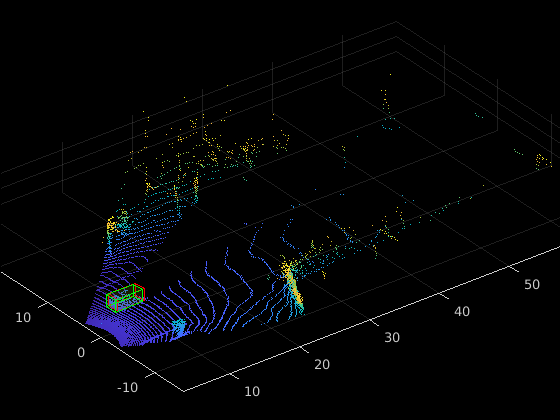

ptCloud = testData{3,1};
gtLabels = testLabels{3,1}{1};

% Display the point cloud.
figure;
ax4 = pcshow(ptCloud.Location);

% The generatePointPillarDetections function detects the bounding boxes, scores for a
% given point cloud.
confidenceThreshold = 0.5;
overlapThreshold = 0.1;
[box,score,labels] = generatePointPillarDetections(net,ptCloud,anchorBoxes,gridParams,classNames,confidenceThreshold,...
                      overlapThreshold,P,N,executionEnvironment);

% Display the detections on the point cloud.
showShape('cuboid', box, 'Parent', ax4, 'Opacity', 0.1, 'Color', 'red','LineWidth',0.5);hold on;
showShape('cuboid', gtLabels, 'Parent', ax4, 'Opacity', 0.1, 'Color', 'green','LineWidth',0.5);
zoom(ax4,2);

## Helper Functions

### Model Gradients

The function `modelGradients` takes as input the [dlnetwork](docid:nnet_ref#object_dlnetwork) object `net` and a mini-batch of input data `pillarFeautures` and `pillarIndices` with corresponding ground truth boxes, anchor boxes and grid parameters. The function returns the gradients of the loss with respect to the learnable parameters in `net`, the corresponding mini-batch loss, and the state of the current batch.

The model gradients function computes the total loss and gradients by performing these operations.

- Extract the predictions from the network using the [forward](docid:nnet_ref#function_forward) function.

- Generate the targets for loss computation by using the ground truth data, grid parameters, and anchor boxes.

- Calculate the loss function for all six predictions from the network.

- Compute the total loss as the sum of all losses.

- Compute the gradients of learnables with respect to the total loss.

function [gradients, loss, state] = modelGradients(net, pillarFeatures, pillarIndices, boxLabels, gridParams, anchorBoxes,...
                                                   executionEnvironment)
      
    % Extract the predictions from the network.
    YPredictions = cell(size(net.OutputNames));
    [YPredictions{:}, state] = forward(net,pillarIndices,pillarFeatures);
    
    % Generate target for predictions from the ground truth data.
    YTargets = generatePointPillarTargets(YPredictions, boxLabels, pillarIndices, gridParams, anchorBoxes);
    YTargets = cellfun(@ dlarray,YTargets,'UniformOutput', false);
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        YTargets = cellfun(@ gpuArray,YTargets,'UniformOutput', false);
    end
     
    [angLoss, occLoss, locLoss, szLoss, hdLoss, clfLoss] = computePointPillarLoss(YPredictions, YTargets);
    
    % Compute the total loss.
    loss = angLoss + occLoss + locLoss + szLoss + hdLoss + clfLoss;
    
    % Compute the gradients of the learnables with regard to the loss.
    gradients = dlgradient(loss,net.Learnables);
 
end

function [pillarFeatures, pillarIndices, labels] = createBatchData(features, indices, groundTruthBoxes, groundTruthClasses, classNames)
% Returns pillar features and indices combined along the batch dimension
% and bounding boxes concatenated along batch dimension in labels.
    
    % Concatenate features and indices along batch dimension.
    pillarFeatures = cat(4, features{:,1});
    pillarIndices = cat(4, indices{:,1});
    
    % Get class IDs from the class names.
    classNames = repmat({categorical(classNames')}, size(groundTruthClasses));
    [~, classIndices] = cellfun(@(a,b)ismember(a,b), groundTruthClasses, classNames, 'UniformOutput', false);
    
    % Append the class indices and create a single array of responses.
    combinedResponses = cellfun(@(bbox, classid)[bbox, classid], groundTruthBoxes, classIndices, 'UniformOutput', false);
    len = max(cellfun(@(x)size(x,1), combinedResponses));
    paddedBBoxes = cellfun( @(v) padarray(v,[len-size(v,1),0],0,'post'), combinedResponses, 'UniformOutput',false);
    labels = cat(4, paddedBBoxes{:,1});
end

function lidarData = downloadWPIData(outputFolder, lidarURL)
% Download the data set from the given URL into the output folder.

    lidarDataTarFile = fullfile(outputFolder,'WPI_LidarData.tar.gz');
    if ~exist(lidarDataTarFile, 'file')
        mkdir(outputFolder);
        
        disp('Downloading WPI Lidar driving data (760 MB)...');
        websave(lidarDataTarFile, lidarURL);
        untar(lidarDataTarFile,outputFolder);
    end
    
    % Extract the file.
    if ~exist(fullfile(outputFolder, 'WPI_LidarData.mat'), 'file')
        untar(lidarDataTarFile,outputFolder);
    end
    load(fullfile(outputFolder, 'WPI_LidarData.mat'),'lidarData');
    lidarData = reshape(lidarData,size(lidarData,2),1);
end

function net = downloadPretrainedPointPillarsNet(outputFolder, pretrainedNetURL)
% Download the pretrained PointPillars detector.

    preTrainedMATFile = fullfile(outputFolder,'trainedPointPillarsNet.mat');
    preTrainedZipFile = fullfile(outputFolder,'trainedPointPillars.zip');
    
    if ~exist(preTrainedMATFile,'file')
        if ~exist(preTrainedZipFile,'file')
            disp('Downloading pretrained detector (8.3 MB)...');
            websave(preTrainedZipFile, pretrainedNetURL);
        end
        unzip(preTrainedZipFile, outputFolder);   
    end
    pretrainedNet = load(preTrainedMATFile);
    net = pretrainedNet.net;       
end

function lossPlotter = configureTrainingProgressPlotter(f)
% The configureTrainingProgressPlotter function configures training
% progress plots for various losses.
    figure(f);
    clf
    ylabel('Total Loss');
    xlabel('Iteration');
    lossPlotter = animatedline;
end

function retValue = checkForNaN(gradients,loss)
% Based on experiments it is found that the last convolution head
% 'occupancy|conv2d' contains NaNs as the gradients. This function checks
% whether gradient values contain NaNs. Add other convolution
% head values to the condition if NaNs are present in the gradients. 
    gradValue = gradients.Value((gradients.Layer == 'occupancy|conv2d') & (gradients.Parameter == 'Bias'));
    if (sum(isnan(extractdata(loss)),'all') > 0) || (sum(isnan(extractdata(gradValue{1,1})),'all') > 0)
        retValue = true;
    else
        retValue = false;
    end
end

### References

[1] Lang, Alex H., Sourabh Vora, Holger Caesar, Lubing Zhou, Jiong Yang, and Oscar Beijbom. "PointPillars: Fast Encoders for Object Detection From Point Clouds." In *2019 IEEE/CVF Conference on Computer Vision and Pattern Recognition *(CVPR), 12689-12697. Long Beach, CA, USA: IEEE, 2019. https://doi.org/10.1109/CVPR.2019.01298.

*Copyright 2020 The MathWorks, Inc.*